# Actividad 4.1 (Evaluación)

Ana Itzel Hernández García A01737526

Esta tarea fue bloqueada 10 de abr en 23:59.

**Implementar** el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D.

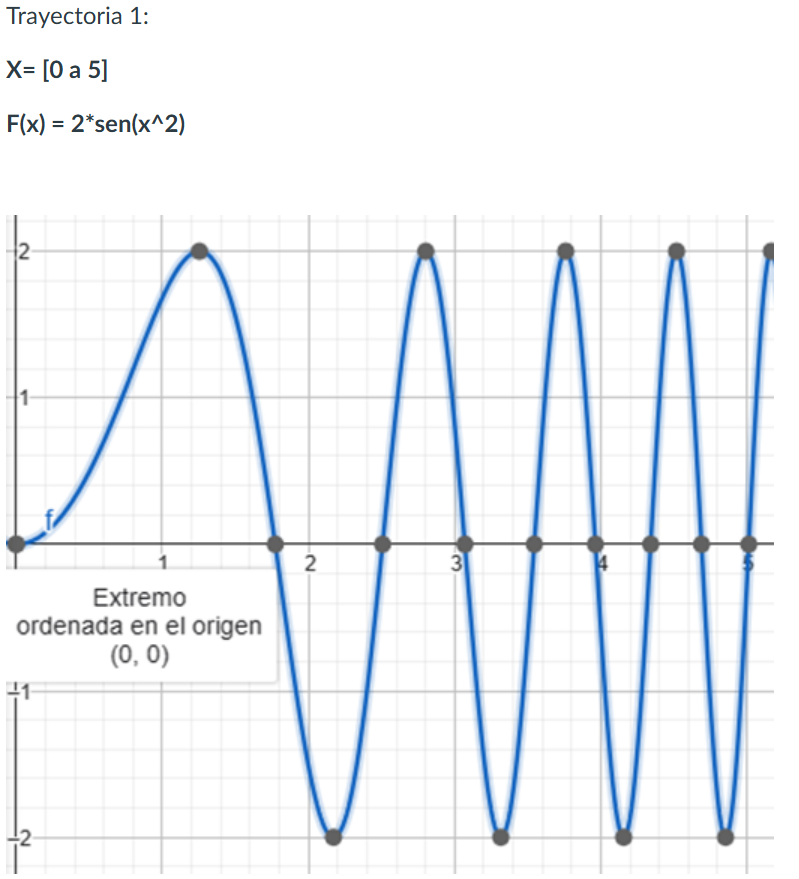 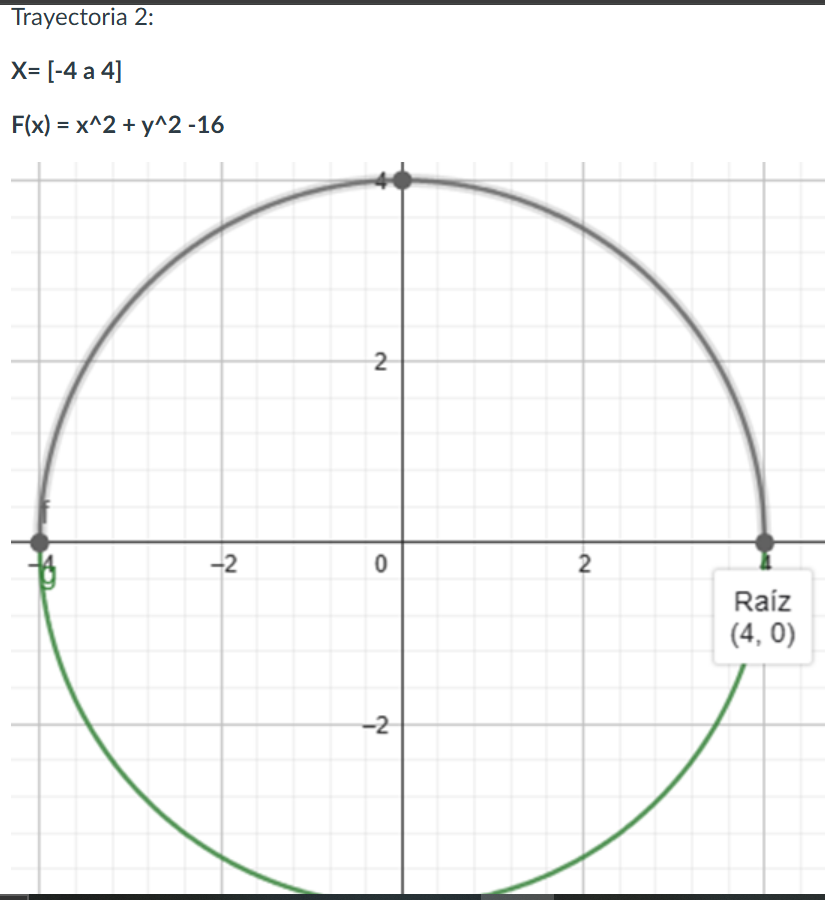 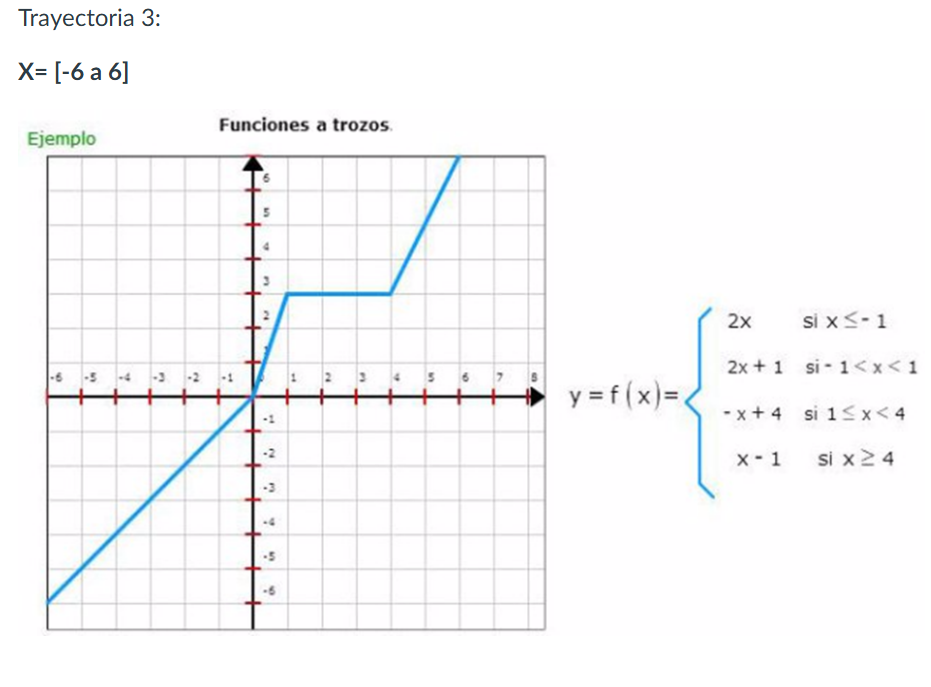

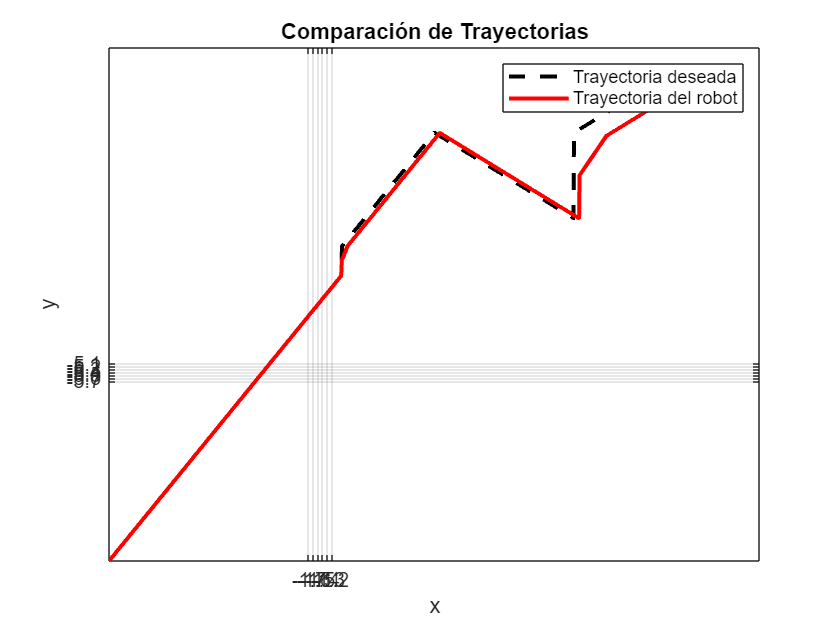


clear all
close all
clc

%%% VELOCIDADES DE REFERENCIA %%%
trace_op = 3;

if trace_op == 1
    %Trayectoria 1

    % Rango de x
    x = 0:0.0025:5;
    % f(x) = 2 * sin(x^2)
    y = 2 * sin(x.^2);

    % Derivadas de la trayectoria 
    dx = gradient(x, 0.1);
    dy = gradient(y, 0.1);
    
    % Orientación del robot en cada punto de la trayectoria
    theta = atan2(dy, dx); 
    
    % Velocidad lineal
    u = sqrt(dx.^2 + dy.^2);  
    u = u / max(u) * 0.5;  % Normalización
    
    % Velocidad angular 
    w = gradient(theta, 0.1);

elseif trace_op == 2
    %Trayectoria 2
    t = 0:0.003:2*pi;
    
    % Coordenadas de la trayectoria
    x = 4 * cos(t); 
    y = 4 * sin(t);

    % Derivadas de la trayectoria
    dx = gradient(x, 0.1);
    dy = gradient(y, 0.1);
    
    % Orientación del robot en cada punto de la trayectoria
    theta = atan2(dy, dx);
    
    % Velocidad lineal 
    u = sqrt(dx.^2 + dy.^2);
    
    % Velocidad angular
    w = gradient(theta, 0.1);

elseif trace_op == 3
    %Trayectoria 3
    
    % Rango de x
    x = -6:0.01:6;
    %Inicialización de Y
    y = zeros(size(x));
    
    %Valores para Y
    for i = 1:length(x)
        if x(i) <= -1
            y(i) = 2 * x(i);
        elseif x(i) > -1 && x(i) < 1
            y(i) = 2 * x(i) + 1;
        elseif x(i) >= 1 && x(i) < 4
            y(i) = -x(i) + 4;
        elseif x(i) >= 4
            y(i) = x(i) - 1;
        end

    end

    % Derivadas de la trayectoria deseada
    dx = gradient(x, 0.1);
    dy = gradient(y, 0.1);
    
    % Dirección de la curva deseada
    theta = atan2(dy, dx);  % ¡Este es el correcto!
    
    % Velocidad constante deseada
    u = sqrt(dx.^2 + dy.^2);  
    
    % Velocidad angular (cambio de orientación)
    w = gradient(theta, 0.1);

end

%%% TIEMPO %%%
N = length(u);  % Muestras
tf = N/10;        % Tiempo de simulación en segundos (s)
ts = 0.1;       % Tiempo de muestreo en segundos (s)

t = linspace(0,tf,N);% t = 0:ts:tf;    % Vector de tiempo


%%% CONDICIONES INICIALES %%%
x1 = zeros(1, N+1); % Posición en el centro del eje que une las ruedas (eje x) en metros
y1 = zeros(1, N+1); % Posición en el centro del eje que una las ruedas (eje y) en metros
phi = zeros(1, N+1); % Orientación del robot en radianes (rad)


if trace_op == 2
    x1(1) = 4;
    y1(1) = 0;
    phi(1) = 2*pi;

elseif trace_op ~= 3 && trace_op ~= 2
    x1(1) = 0;  % Posición inicial eje x
    y1(1) = 0;  % Posición inicial eje y
    phi(1) = 0;  % Orientación inicial del robot
else
    x1(1) = x(1);
    y1(1) = y(1);
    phi(1) = theta(1);
end 

%%% PUNTO DE CONTROL %%%
hx = zeros(1, N+1); % Posición en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1); % Posición en el punto de control (eje y) en metros (m)

hx(1) = x1(1);  % Posición en el punto de control del robot en el eje x
hy(1) = y1(1);  % Posición en el punto de control del robot en el eje y
phi(1) = theta(1);  % Inicializa con la misma orientación


l = 0.157;
r = 0.05;

w_r = (2*u + w*l)/(2*r);
w_l = (2*u - w*l)/(2*r);

pose_xp = zeros(1,N);
pose_yp = zeros(1,N);
pose_thp = zeros(1,N);


%%% BUCLE DE SIMULACION %%%
for k = 1:N
    
    phi(k+1) = phi(k) + w(k)*ts;    % Integral numérica (método de Euler)
    
    %%% MODELO CINEMATICO %%%
    xp1 = u(k)*cos(phi(k+1));
    yp1 = u(k)*sin(phi(k+1));
    


    x1(k+1) = x1(k) + xp1*ts; % Integral numérica (método de Euler)
    y1(k+1) = y1(k) + yp1*ts; % Integral numérica (método de Euler)
    
    pose_xp(k) = x1(k);
    pose_yp(k) = y1(k);
    pose_thp(k) = phi(k);
    
    % Posición del robot con reespecto a l punto de control
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end


pose_thp = rad2deg(phi(1:N)); 

figure;
plot(x, y, 'k--', 'LineWidth', 2); hold on;
plot(hx, hy, 'r', 'LineWidth', 2);
legend('Trayectoria deseada', 'Trayectoria del robot');
xlabel('x'); ylabel('y'); title('Comparación de Trayectorias'); grid on;

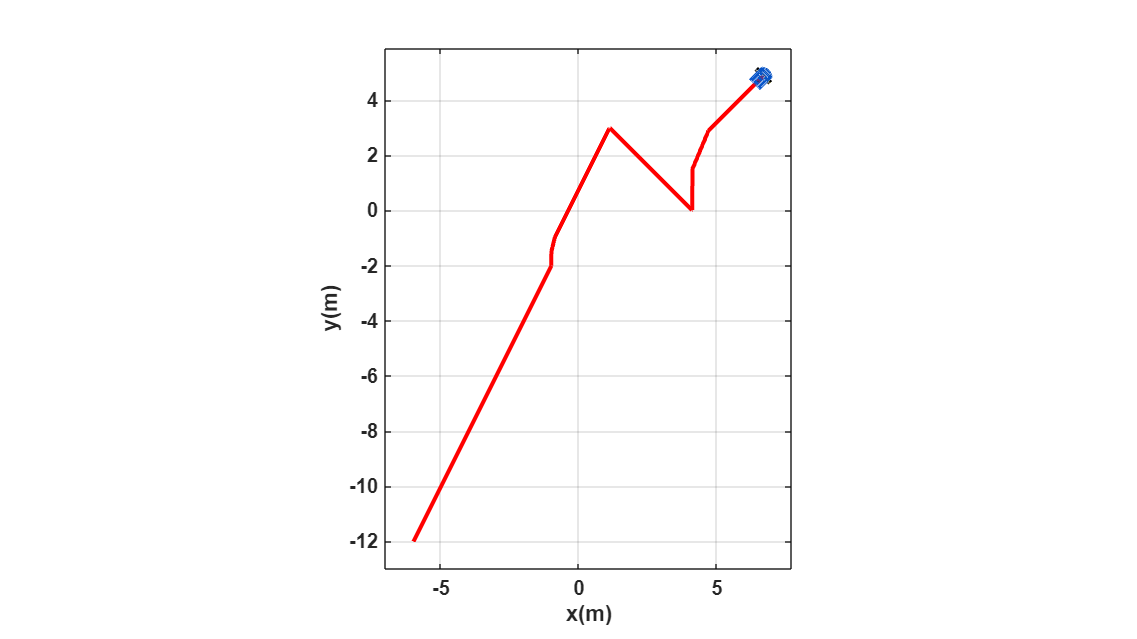

%a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view(2); % Orientacion de la figura
axis([min(x1)-1, max(x1)+1, min(y1)-1, max(y1)+1, 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);


% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

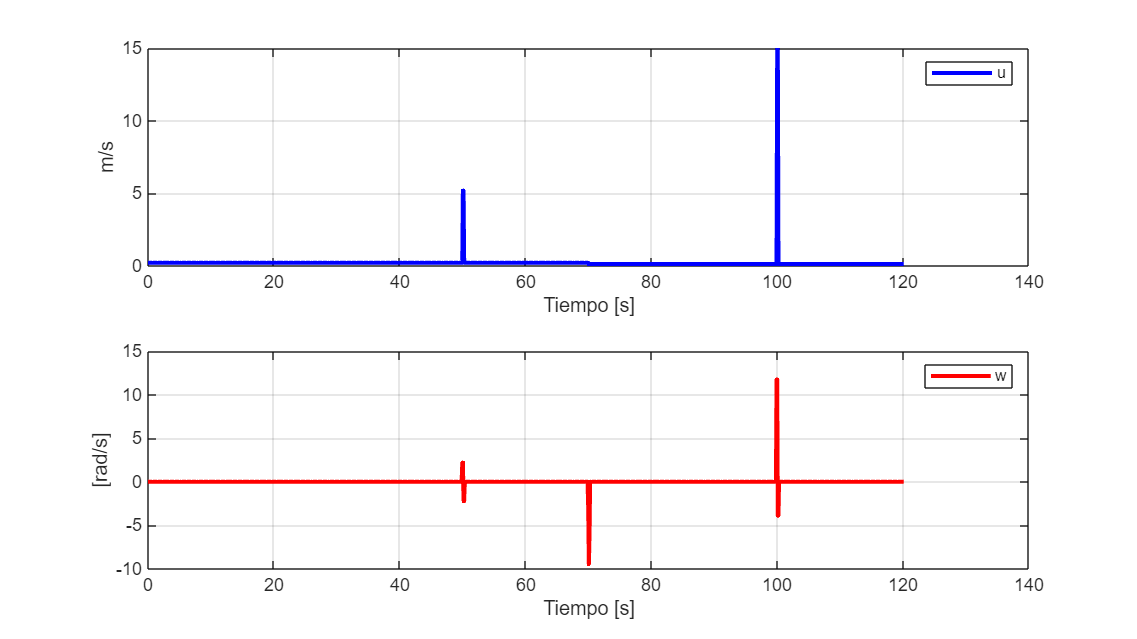


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

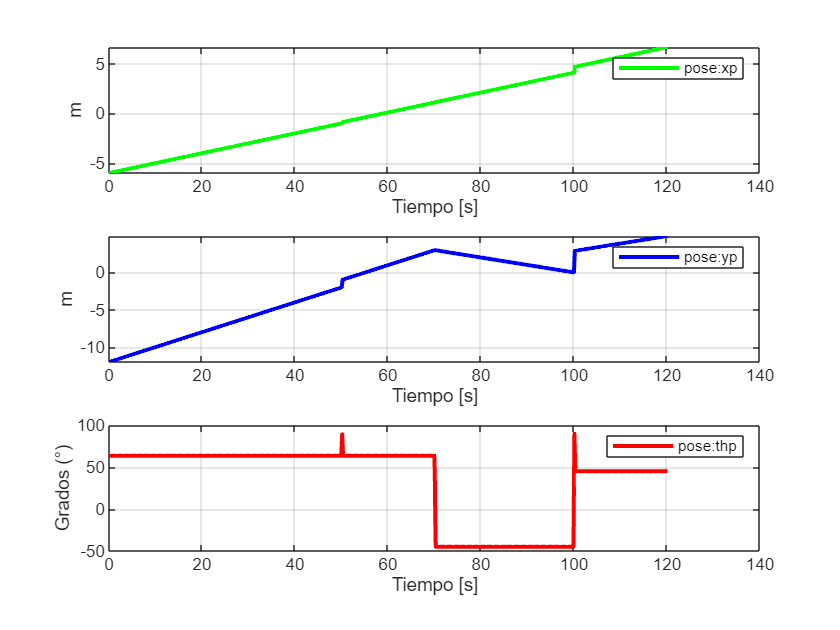


figure;
subplot(3,1,1)
plot(t,pose_xp, 'g', 'LineWidth', 2), grid('on'),xlabel('Tiempo [s]'),ylabel('m'),legend('pose:xp');

subplot(3,1,2)
plot(t,pose_yp, 'b', 'LineWidth', 2), grid('on'),xlabel('Tiempo [s]'),ylabel('m'),legend('pose:yp');

subplot(3,1,3)
plot(t,pose_thp, 'r', 'LineWidth', 2), grid('on'),xlabel('Tiempo [s]'),ylabel('Grados (°)'),legend('pose:thp');

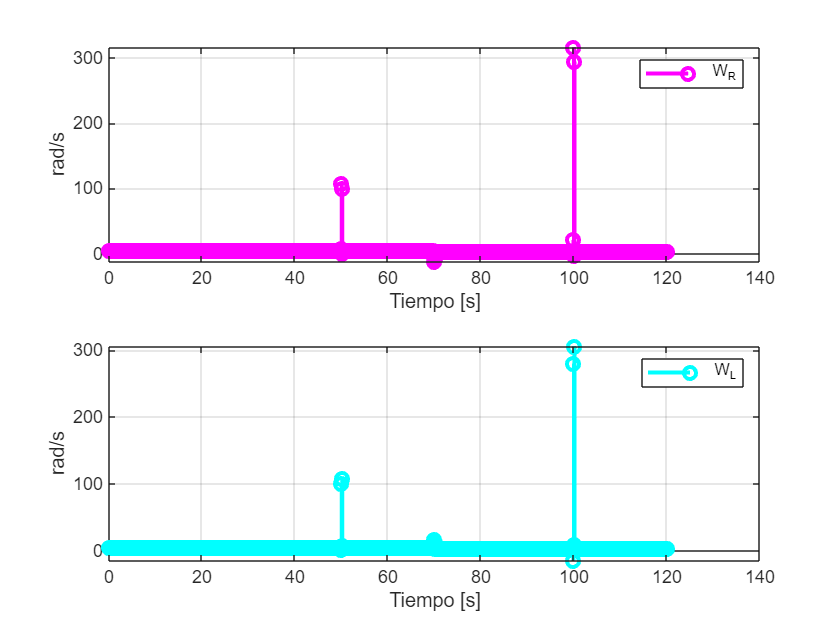


figure;
subplot(2,1,1)
stem(t,w_r, 'm', 'LineWidth', 2), grid('on'),xlabel('Tiempo [s]'),ylabel('rad/s'),legend('W_R');
subplot(2,1,2)
stem(t,w_l, 'c', 'LineWidth', 2), grid('on'),xlabel('Tiempo [s]'),ylabel('rad/s'),legend('W_L');